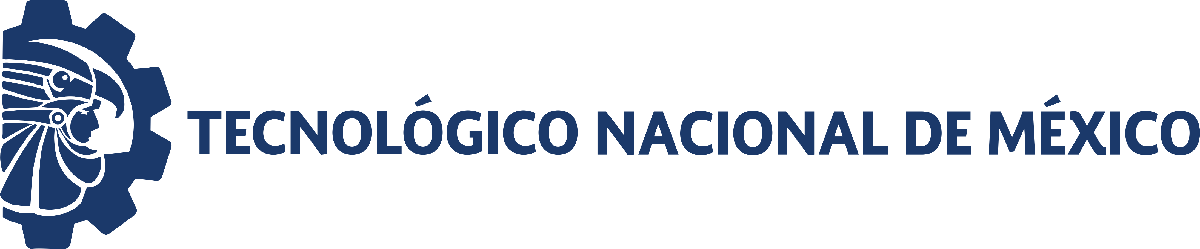                                 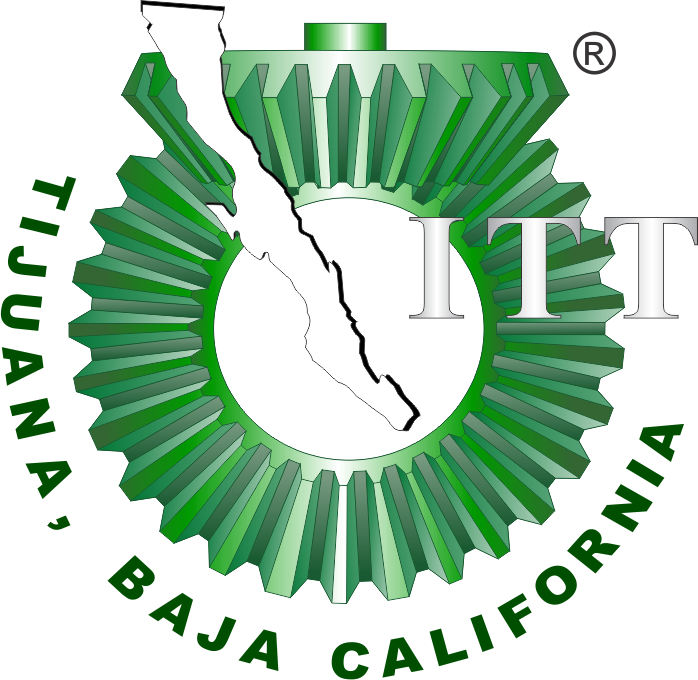

# Práctica tres: Sistema Muscoloesqueletico  

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

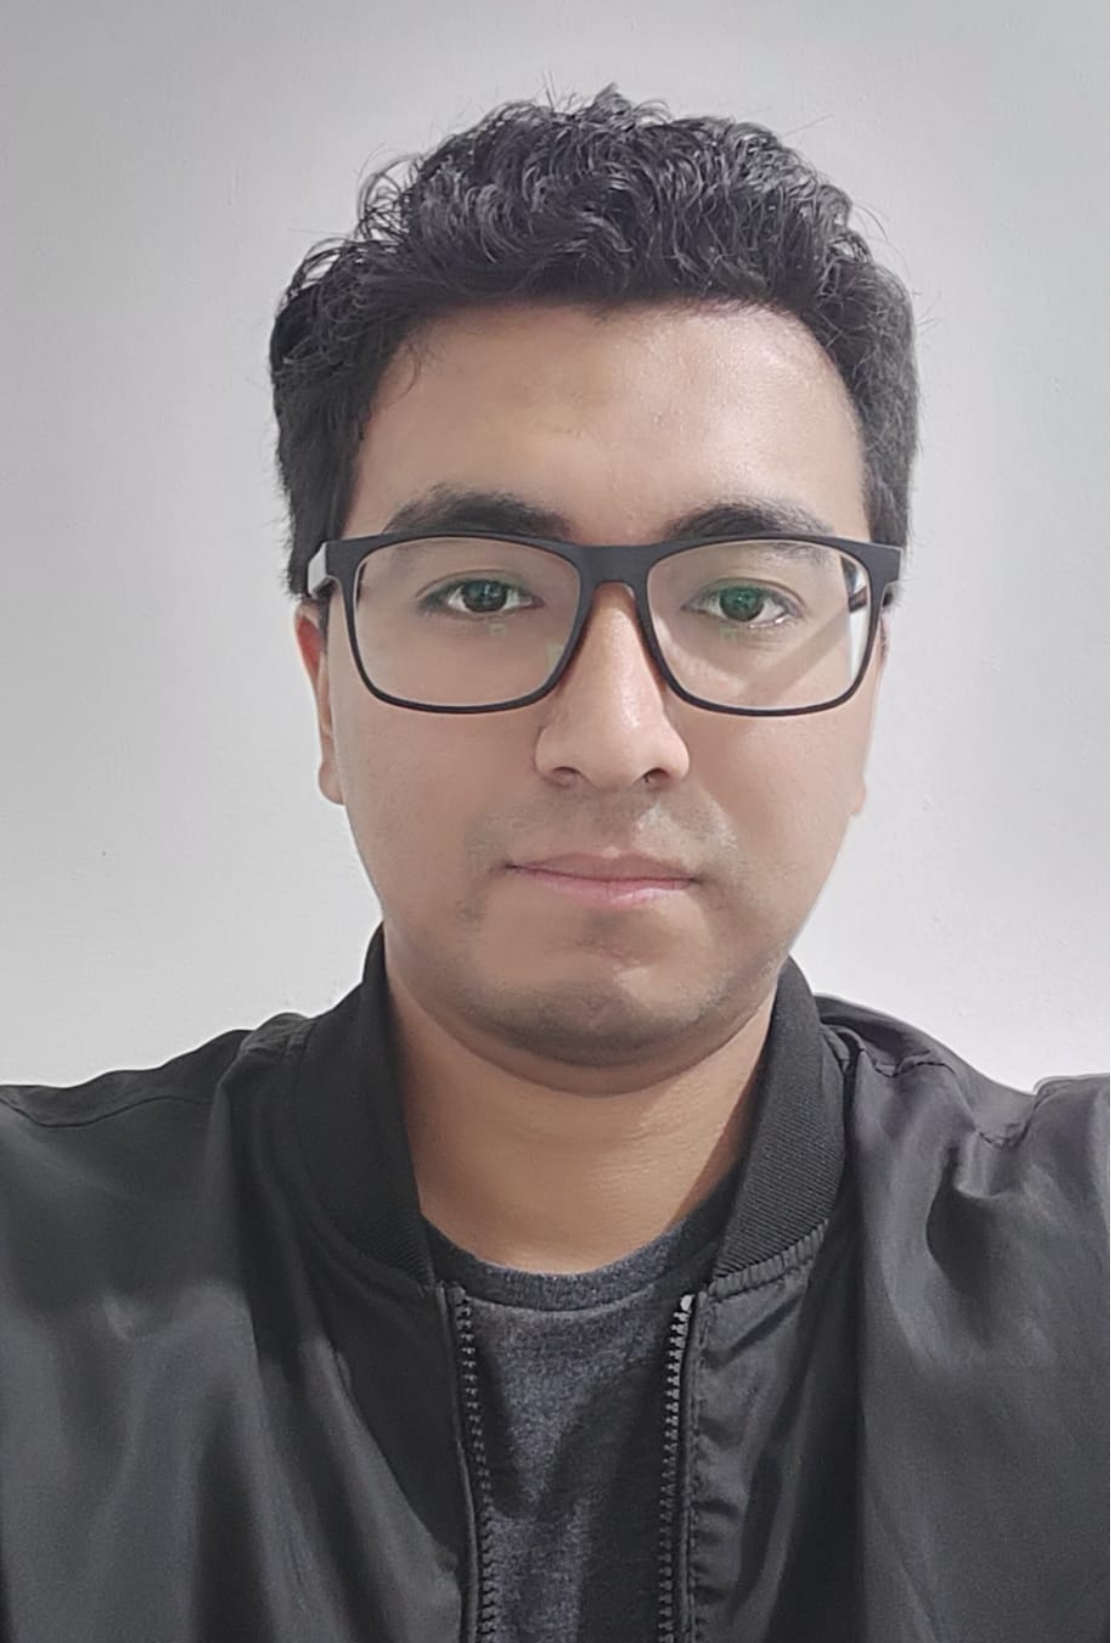

Nombre del alumno: Carlos Daniel Frausto Luna

Número de control: C18210366

Correo institucional: LC18210366**@tijuana.tecnm.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

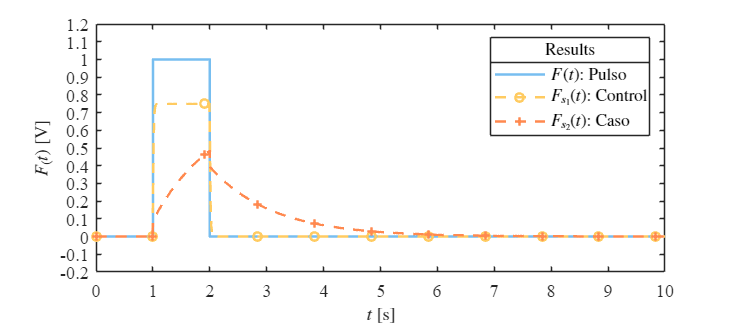

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema_Pra_3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
set_param('Sistema_Pra_3/F(t)','Amplitude','1');
set_param('Sistema_Pra_3/F(t)','Period','10');
set_param('Sistema_Pra_3/F(t)','PulseWidth','10');
set_param('Sistema_Pra_3/F(t)','Phasedelay','1');
x = sim(file,parameters);
x1 = sim(file,parameters);
plotsignals(x1.t, x1.F, x1.Fs1, x1.Fs2, [], 'Lazo abierto');

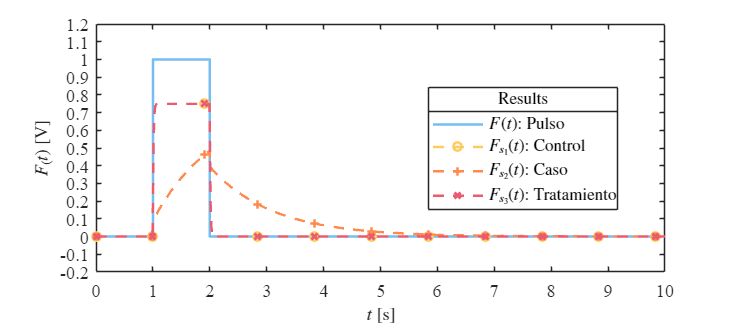

plotsignals(x.t,x.F,x.Fs1,x.Fs2,x.Fs3,'Lazo Cerrado');

## Funcion: respuesta a las señales

function plotsignals(t, F, Fs1, Fs2, Fs3, name)
    t   = t(:);
    F = F(:);
    Fs1 = Fs1(:);
    Fs2 = Fs2(:);
    Fs3 = Fs3(:);

    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off, box on;
    mycolors = [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50]/255;
    colororder(mycolors)
    vars = {F, Fs1, Fs2, Fs3};
    labels = {'$F(t)$: Pulso', ...
              '$F_{s_1}(t)$: Control', ...
              '$F_{s_2}(t)$: Caso', ...
              '$F_{s_3}(t)$: Tratamiento'};
    estilos = {'-', '--o', '--+', '--x', ':'};

    p = [];
    for i = 1:length(vars)
        if ~isempty(vars{i})
            p(end+1) = plot(t, vars{i}, estilos{i}, 'LineWidth', 1.5, ...
                'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
        end
    end

    if length(p) >= 5
        set(p(5),'LineWidth',3);
    end

    L = legend(p, labels{1:length(p)}, 'Interpreter', 'Latex', ...
        'FontSize', 10, 'Location', 'Best', 'Box', 'On');
    title(L,'Results','FontSize',10);

    xlabel('$t$ [s]', 'Interpreter', 'Latex', 'FontSize', 11)
    ylabel('$F_(t)$ [V]', 'Interpreter', 'Latex', 'FontSize', 11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.2,1.2]);yticks(-0.2:0.1:1.2);
    
    exportgraphics(gcf,[name,'.pdf'],'ContentType','vector');
    exportgraphics(gcf,[name,'.png'],'ContentType','vector');
end